**CONSTRUCTIVE AND ITERATIVE METHODS FOR CVRP**

Annalisa Deiana (292286), Giorgia delle Grazie (300879), Elisa Salvadori (302630).

clear
close all
clc

We use a cluster-first, route-second approach. We find a solution for the CVRP with a constructive method and then we try to improve this solution using an iterative method. This idea may lead to a locally optimal solution due to the local search approach of the iterative method. 

We used the following links to write the code. 

**References**

[https://pubsonline.informs.org/doi/abs/10.1287/opre.22.2.340](https://pubsonline.informs.org/doi/abs/10.1287/opre.22.2.340)

[https://snipplr.com/view/4064/shortest-path-heuristics-nearest-neighborhood-2-opt-farthest-and-arbitrary-insertion-for-travelling-salesman-problem](https://snipplr.com/view/4064/shortest-path-heuristics-nearest-neighborhood-2-opt-farthest-and-arbitrary-insertion-for-travelling-salesman-problem)

[https://it.mathworks.com/matlabcentral/fileexchange/71226-tspsearch](https://it.mathworks.com/matlabcentral/fileexchange/71226-tspsearch)

**Data1**

It's the dataset of the Milk collection.

East = [0 -3 1 4 -5 -5 -4 6 3 -1 0 6 2 -2 6 1 -3 -6 2 -6 5]; %x
North = [0 3 11 7 9 -2 -7 0 -6 -3 -6 4 5 8 10 8 1 5 9 -5 -4]; %y
N = length(East); %number of locations including the depot
Q = [0 5 4 3 6 7 3 4 6 5 4 7 3 4 5 6 8 5 7 6 6]; %demand at location i
% 1 is the location of the depot
cap = 20; %capacity of vehicle

**Code costructive1**

Length_tot_constructive = 0;

[finalroutes,numclusters] = sweep(East, North, Q, cap)

finalroutes = 6×1 cell array
    {5×1 double}
    {5×1 double}
    {5×1 double}
    {3×1 double}
    {5×1 double}
    {3×1 double}


numclusters = 6

OK: Every test passed. 


path =      1     2     3     4     5     1


total_length = 28

location_cluster =      0     0
     6     0
     6     4
     6    10
     4     7


path =      1     2     4     3     5     1


total_length = 22

location_cluster =      0     0
     2     5
     2     9
     1     8
     1    11


path =      1     2     3     5     4     1


total_length = 23

location_cluster =      0     0
    -2     8
    -5     9
    -3     3
    -6     5


path =      1     2     3     1


total_length = 12

location_cluster =      0     0
    -3     1
    -5    -2


path =      1     4     5     3     2     1


total_length = 21

location_cluster =      0     0
    -6    -5
    -4    -7
    -1    -3
     0    -6


path =      1     3     2     1


total_length = 16

location_cluster =      0     0
     3    -6
     5    -4


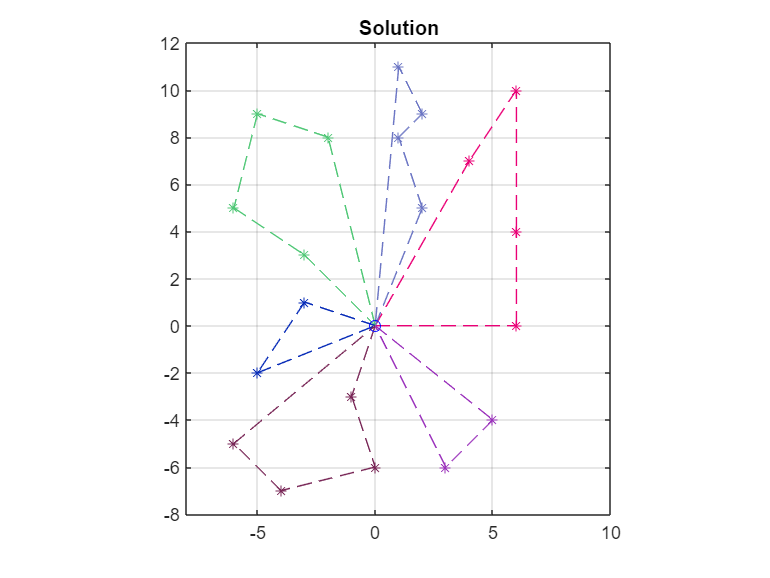


path_tot = cell(numclusters,1);

for k = 1:numclusters
%check the data
result = check(East, North, Q, finalroutes{k}, cap);
end

if result == 'true'
    fprintf('OK: Every test passed. \n');

    figure
    for j = 1:numclusters
    
        [path, total_length, location_cluster] = farthest_insertion_heuristic(finalroutes{j}, East, North) 
        path_tot{j} = path;
        Length_tot_constructive = Length_tot_constructive + total_length;
    
        color = rand(1,3);
 
        p1 = plot(location_cluster(1,1), location_cluster(1,2), 'bo');
        axis equal
        hold on
        
        p1 = plot(location_cluster(2:end,1), location_cluster(2:end,2), '*', 'Color', color);
        hold on

        p1 = plot([location_cluster(path(1),1), location_cluster(path(end),1)],...
            [location_cluster(path(1),2), location_cluster(path(end),2)], '--', 'Color', color);
        hold on

        for i = 1:length(finalroutes{j})
                    p1 = plot([location_cluster(path(i),1), location_cluster(path(i+1),1)],...
                        [location_cluster(path(i),2), location_cluster(path(i+1),2)], '--', 'Color', color);
                    hold on
        end
        xlim([-8.0 10.0])
        ylim([-8.0 12.0])
        title('Solution')
        grid on
    end
end

fprintf('The total length of the constructive method is: %d', Length_tot_constructive);

The total length of the constructive method is: 122

**Code iterative1**

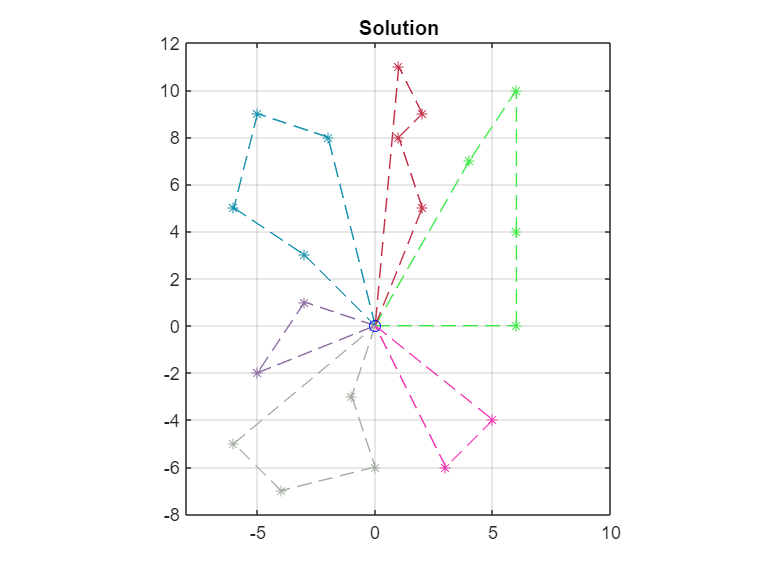

path =      1     2     3     4     5     1


total_length = 28

location_cluster =      0     0
     6     0
     6     4
     6    10
     4     7


path =      1     2     4     3     5     1


total_length = 22

location_cluster =      0     0
     2     5
     2     9
     1     8
     1    11


path =      1     2     3     5     4     1


total_length = 23

location_cluster =      0     0
    -2     8
    -5     9
    -3     3
    -6     5


path =      1     2     3     1


total_length = 12

location_cluster =      0     0
    -3     1
    -5    -2


path =      1     4     5     3     2     1


total_length = 21

location_cluster =      0     0
    -6    -5
    -4    -7
    -1    -3
     0    -6


path =      1     3     2     1


total_length = 16

location_cluster =      0     0
     3    -6
     5    -4


Length_tot_iterative = 0;

figure
for j = 1:numclusters
    
    [path, total_length, location_cluster] = two_opt_heuristic(path_tot{j}, finalroutes{j}, East, North)
    Length_tot_iterative = Length_tot_iterative + total_length;

    color = rand(1,3);
 
        p1 = plot(location_cluster(1,1), location_cluster(1,2), 'bo');
        axis equal
        hold on
        
        p1 = plot(location_cluster(2:end,1), location_cluster(2:end,2), '*', 'Color', color);
        hold on

        p1 = plot([location_cluster(path(1),1), location_cluster(path(end),1)],...
            [location_cluster(path(1),2), location_cluster(path(end),2)], '--', 'Color', color);
        hold on

        for i = 1:length(finalroutes{j})
                    p1 = plot([location_cluster(path(i),1), location_cluster(path(i+1),1)],...
                        [location_cluster(path(i),2), location_cluster(path(i+1),2)], '--', 'Color', color);
                    hold on
        end
        xlim([-8.0 10.0])
        ylim([-8.0 12.0])
        title('Solution')
        grid on
end

fprintf('The total length of the iterative method is: %d', Length_tot_iterative);

The total length of the iterative method is: 122

**Conclusion1**

The solution found with the constructive method is the same of the one of the iterative method.

clear

**Data2**

E-n30-k3 dataset: [http://vrp.atd-lab.inf.puc-rio.br/index.php/en/](http://vrp.atd-lab.inf.puc-rio.br/index.php/en/).

East = [162 218 218 201 214 224 210 104 126 119 129 126 125 116 126 125 119 115 153 175 180 159 188 152 215 212 188 207 184 207]; %x
North = [354 382 358 370 371 370 382 354 338 340 349 347 346 355 335 355 357 341 351 363 360 331 357 349 389 394 393 406 410 392]; %y
N = length(East); %number of locations including the depot
Q = [0 300 3100 125 100 200 150 150 450 300 100 950 125 150 150 550 150 100 150 400 300 1500 100 300 500 800 300 100 150 1000]; %demand at location i
% 1 is the location of the depot
cap = 4500; %capacity of vehicle

**Code costructive2**

Length_tot_constructive = 0;

[finalroutes,numclusters] = sweep(East, North, Q, cap)

finalroutes = 3×1 cell array
    { 8×1 double}
    { 9×1 double}
    {15×1 double}


numclusters = 3

OK: Every test passed. 


path =      1     8     7     6     5     4     3     2     1


total_length = 165

location_cluster =    162   354
   218   358
   224   370
   214   371
   218   382
   215   389
   210   382
   201   370


path =      1     8     7     6     4     3     2     5     9     1


total_length = 202

location_cluster =    162   354
   212   394
   207   392
   188   357
   207   406
   180   360
   175   363
   159   331
   188   393


path =      1     3     4     7     8     9     6     5    11    12    15    14    13    10     2     1


total_length = 243

location_cluster =    162   354
   184   410
   153   351
   152   349
   126   335
   126   338
   129   349
   126   347
   125   346
   125   355


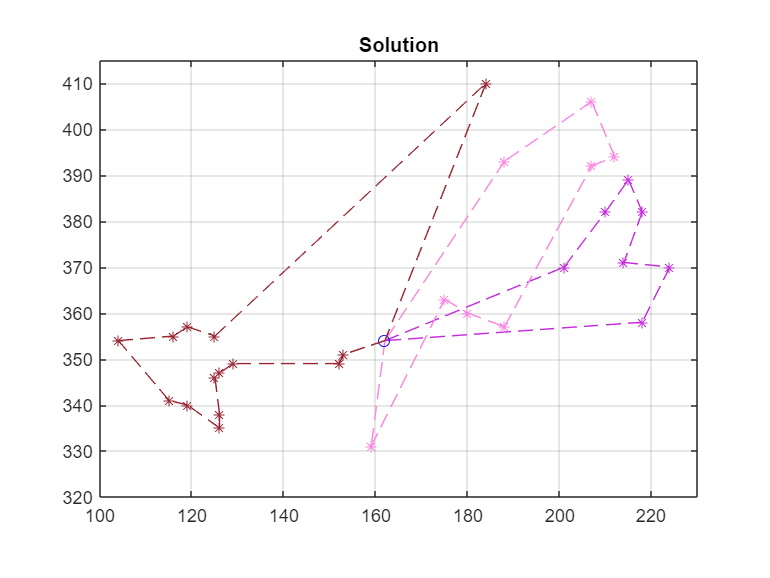


path_tot = cell(numclusters,1);

for k = 1:numclusters
%check the data
result = check(East, North, Q, finalroutes{k}, cap);
end

if result == 'true'
    fprintf('OK: Every test passed. \n');

    figure
    for j = 1:numclusters
    
        [path, total_length, location_cluster] = farthest_insertion_heuristic(finalroutes{j}, East, North) 
        path_tot{j} = path;
        Length_tot_constructive = Length_tot_constructive + total_length;
    
        color = rand(1,3);
 
        p1 = plot(location_cluster(1,1), location_cluster(1,2), 'bo');
        axis equal
        hold on
        
        p1 = plot(location_cluster(2:end,1), location_cluster(2:end,2), '*', 'Color', color);
        hold on

        p1 = plot([location_cluster(path(1),1), location_cluster(path(end),1)],...
            [location_cluster(path(1),2), location_cluster(path(end),2)], '--', 'Color', color);
        hold on

        for i = 1:length(finalroutes{j})
                    p1 = plot([location_cluster(path(i),1), location_cluster(path(i+1),1)],...
                        [location_cluster(path(i),2), location_cluster(path(i+1),2)], '--', 'Color', color);
                    hold on
        end
        xlim([100 230])
        ylim([320 415])
        title('Solution')
        grid on
    end
end

fprintf('The total length of the constructive method is: %d', Length_tot_constructive);

The total length of the constructive method is: 610

**Code iterative2**

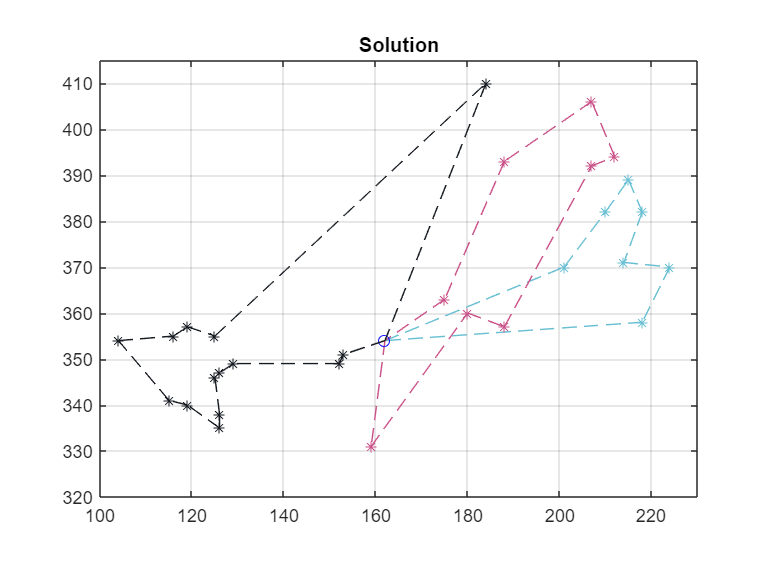

path =      1     8     7     6     5     4     3     2     1


total_length = 165

location_cluster =    162   354
   218   358
   224   370
   214   371
   218   382
   215   389
   210   382
   201   370


path =      1     8     6     4     3     2     5     9     7     1


total_length = 198

location_cluster =    162   354
   212   394
   207   392
   188   357
   207   406
   180   360
   175   363
   159   331
   188   393


path =      1     3     4     7     8     9     6     5    11    12    15    14    13    10     2     1


total_length = 243

location_cluster =    162   354
   184   410
   153   351
   152   349
   126   335
   126   338
   129   349
   126   347
   125   346
   125   355


Length_tot_iterative = 0;

figure
for j = 1:numclusters

    [path, total_length, location_cluster] = two_opt_heuristic(path_tot{j}, finalroutes{j}, East, North)
    Length_tot_iterative = Length_tot_iterative + total_length;

    color = rand(1,3);
 
    p1 = plot(location_cluster(1,1), location_cluster(1,2), 'bo');
    axis equal
    hold on
    
    p1 = plot(location_cluster(2:end,1), location_cluster(2:end,2), '*', 'Color', color);
    hold on

    p1 = plot([location_cluster(path(1),1), location_cluster(path(end),1)],...
        [location_cluster(path(1),2), location_cluster(path(end),2)], '--', 'Color', color);
    hold on

    for i = 1:length(finalroutes{j})
                p1 = plot([location_cluster(path(i),1), location_cluster(path(i+1),1)],...
                    [location_cluster(path(i),2), location_cluster(path(i+1),2)], '--', 'Color', color);
                hold on
    end
    xlim([100 230])
    ylim([320 415])
    title('Solution')
    grid on
end

fprintf('The total length of the iterative method is: %d', Length_tot_iterative);

The total length of the iterative method is: 606

**Conclusion2**

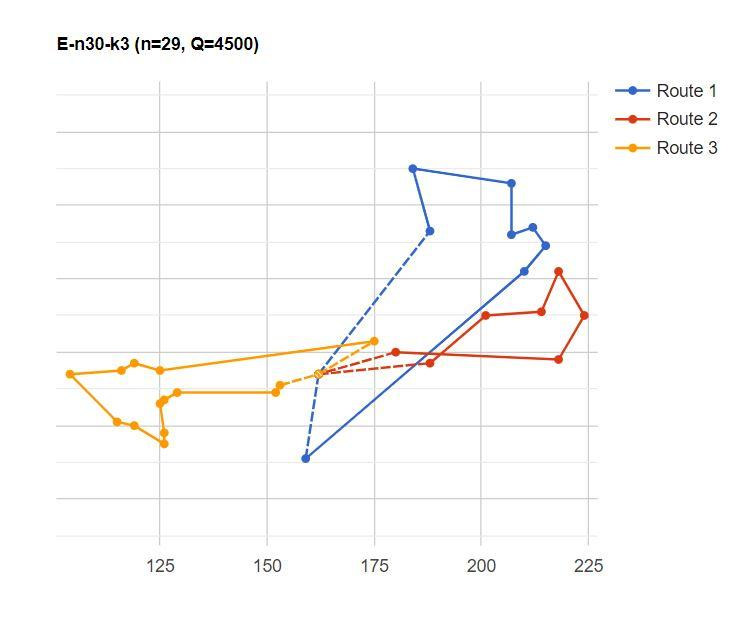

In this case we could note that the iterative method has improved the solution of the constructive one. Our solution is slightly different from the one proposed by the CVRPLIB because the solution has been found with the sweep algorithm and we have obtained different clusters. 

**Functions**

Function *sweep *is used to create clusters. It is a method to make clusters based on the polar coord angle of each point. 

The idea is to draw a ray from the depot and when rotating it we "sweep" customers in an order depending on their location, until one costumer exceeds the capacity.

function [finalroutes,numclusters] = sweep(East, North, Q, cap) 
% % INPUT:
% % East = coordinate x of locations;
% % North = coordinate y of locations;
% % Q = demand at locations i;
% % cap = capacity of vehicle;
% % OUTPUT:
% % finalroutes = array of routes;
% % numclusters = number of clusters.

    n = length(East);

    %compute the polar coord angle for each point, degrees of each angle between 0 and 360
    Angledegr =  mod(atan2d(North,East),360);
    Angle = [Angledegr;1:n];   %1:n to save which point we consider
    Angle = Angle';
    
    %I don't need the depot for these quantities
    Anglenodep = Angle(2:end, :);

    %sort the location based on the angle
    K = sortrows(Anglenodep);
    
    %routes:
    
    %initialize the matrix where we'll write the customers
    routes = zeros(n);  
    
    %initialize the capacity, as first value we take the capacity needed by the first customer (the one with smaller angle)
    sumcap = Q(K(1,2)); 
    
    %the first customer of the first route is the one with smaller angle
    routes(1,1) = K(1,2);
    
    i = 1;
    for j = 2:n-1  
        if sumcap + Q(K(j,2)) > cap %if we exceed the capacity value, assign that
            sumcap = Q(K(j,2));     %customer to the next route (to the next cluster)
            i = i+1;
            routes(i,j) = K(j,2);
         else
            routes(i,j) = K(j,2);            %if we don't exceed capacity, add that
            sumcap = sumcap + Q(K(j,2));    %customer to the current row, sum the demand 
         end 
    end
    
   
    % number of clusters found = number of rows with non zero elements of matrix routes
    numclusters = nnz(any(routes,2));
    
    %add the depot to every row i.e. to every cluster 
    v = [ones(numclusters,1); zeros(n-numclusters,1) ];
    routes = [v, routes];
    
    %cell array to have the customer divided in cluster 
    finalroutes = cell(numclusters,1);
    for w = 1:numclusters
        finalroutes{w} = nonzeros(routes(w,:));
    end
end

Function *check *is used to check the data.

function result = check(East, North, Q, cluster, cap)
% % INPUT:
% % East = coordinate x of locations;
% % North = coordinate y of locations;
% % Q = demand at locations i;
% % cluster = cluster;
% % cap = capacity of vehicle;
% % OUTPUT:
% % result = true if every test passed or false otherwise.

    result = 'true';

    if (length(East) ~= length(North))
        fprintf('ERROR: dimension of East and North arent the same. \n')
        result = 'false';
    end

    if (length(East) ~= length(Q))
        fprintf('ERROR: dimension of Q. \n')
        result = 'false';
    end

    cap_cluster = 0;
    for i = 2:length(cluster)
        cap_cluster = cap_cluster + (Q(cluster(i)));
    end

    if(cap < cap_cluster)
        fprintf('ERROR: lack of capacity. \n');
        result = 'false';
    end
end


Function *farthest_insertion_heuristic *is the main function of the constructive method. 

This method begins with the depot, chooses the farthest point and connects the depot with it. The point outside the path that is the farthest from each point of the path is found and is added in the position that minimizes the extra mileage.

function [path, total_length, location_cluster] = farthest_insertion_heuristic(cluster, East, North)
% % INPUT:
% % cluster = cluster;
% % East = coordinate x of locations;
% % North = coordinate y of locations;
% % OUTPUT:
% % path = path of the cluster;
% % total_length = length of the path;
% % location_cluster = location for each point of the cluster.
    
    n = length(cluster);

    %matrix with coordinates of each points of cluster
    location_cluster = zeros(n,2);
    location_cluster(1,1) = East(1); %x of the depot
    location_cluster(1,2) = North(1); %y of the depot
    for i = 2:n
        location_cluster(i,1) = East(cluster(i));
        location_cluster(i,2) = North(cluster(i));
    end
    
    d = distance(location_cluster);

    %path to be filled with the order in which we visit the points of the cluster
    path = [];
    
    %rename points, the depot is 1, the next in the cluster is 2...
    outside = 1:n;
    
    %add the depot with index 1 in the path
    path(1) = 1;

    [path,outside] = add_to_path(path, outside, outside(1), 2);
    
    for i = 1:n-1

        %find the farthest point from the subroute i.e. the point outside
        %the path that is the farthest from each point of the path
        next_point = farthest_insertion(path, outside, d);
    
        %find the position of the point in the path i.e. the index that
        %minimizes the extra mileage
        entry_position = find_entry_position(d, next_point, path);
    
        %add the point in the position found and update path and outside
        [path,outside] = add_to_path(path, outside, next_point, entry_position);

    end

    %compute the length of the path
    total_length = total_length_of_path(d,path);

    function entry_position = find_entry_position(distances, next_point, path)
    min_increase = inf;
    
    for i = 1:(length(path)-1)
        if (distances(path(i), next_point) + distances(path(i+1), next_point)...
                - distances(path(i), path(i+1))) < min_increase
            min_increase = (distances(path(i), next_point) + distances(path(i+1), next_point)...
                - distances(path(i), path(i+1)));
            entry_position = i+1;
        end
    end
    end

    %compute distances between each node outside the tour and each node in the
    %tour and take the farthest
    function next_point = farthest_insertion(path, outside, distances)
    max_distance = 0;
    for i = 1:length(path)
        for j = 1:length(outside)
            if distances(path(i), outside(j)) > max_distance
                max_distance = distances(path(i), outside(j));
                next_point = outside(j);
            end
        end
    end
    end
    
    %add point to the path 
    function [path,outside] = add_to_path(path, outside, entering_city, entry_position)
        %save the old path
        old_path = path;

        %remove the point to be added to the path from the outside points
        outside(outside == entering_city) = [];
        %add the point to the path
        path(entry_position) = entering_city;
        %every point in the old path is shifted of 1 position
        for i = entry_position:length(old_path)
            path(i+1) = old_path(i); 
        end
    end
    
    
    function d = distance(location) 
    %compute the distance between every pair of points
    n = length(location);
    d = zeros(n,n);
    for i = 1:n
        for j = i+1:n
            d(i,j) = round(norm(location(i,:) - location(j,:)));
            d(j,i) = d(i,j);
        end
    end
    end

    function total_length = total_length_of_path(distances,path)
    total_length = 0;
    for i = 1:length(path)-1
        total_length = total_length + distances(path(i), path(i+1));
    end
    total_length = total_length + distances(path(end), path(1));
    end

end

Function *two_opt_heuristic *is the main function of the iterative method. It is an iterative function for improving the path.

Considering all pairs of nonconsecutive arcs we replace two arcs with two alternative arcs for decreasing the total length of the path i.e. we exchange the edge pair (12,34) with the pair (13,24).

function [path, total_length, location_cluster] = two_opt_heuristic(path, cluster, East, North)
% % INPUT:
% % path = initial path of the cluster;
% % cluster = cluster;
% % East = coordinate x of locations;
% % North = coordinate y of locations;
% % OUTPUT:
% % path = final path of the cluster;
% % total_length = length of the path;
% % location_cluster = location for each point of the cluster.

    nn = length(cluster);

    %matrix with coordinates of each points of cluster
    location_cluster = zeros(nn,2);
    location_cluster(1,1) = East(1); %x of the depot
    location_cluster(1,2) = North(1); %y of the depot
    for i = 2:nn
        location_cluster(i,1) = East(cluster(i));
        location_cluster(i,2) = North(cluster(i));
    end
    

    dist = distance(location_cluster);
    n = length(path);

    
    %Total path length
    total_length = dist(path(n), path(1));
    for j = 2:n
        total_length = total_length + dist(path(j-1), path(j));
    end
    
    dist_min = -total_length;
    
    while dist_min/total_length < -1e-6
    
        dist_min = 0;
        i = 0;
        b = path(n);
    
        %find the best solution to minimize the length
        while i < n-2
            a = b;
            i = i+1;
            b = path(i);
            dist_ab = dist(a,b);
            j = i+1;
            d = path(j);
            while j < n
                c = d;
                j = j+1;
                d = path(j);
                Dist = (dist(a,c) - dist(c,d)) + dist(b,d) - dist_ab;
                if Dist < dist_min
                    dist_min = Dist;
                    imin = i;
                    jmin = j;
                end
            end
        end
    
        %Apply exchange
        if dist_min < 0
            path(imin:jmin-1) = path(jmin-1:-1:imin);
            total_length = total_length + dist_min;
        end    
    end

    function d = distance(location) 
    %compute the distance between every pair of points
    n = length(location);
    d = zeros(n,n);
    for i = 1:n
        for j = i+1:n
            d(i,j) = round(norm(location(i,:) - location(j,:)));
            d(j,i) = d(i,j);
        end
    end
    end

end